**Lab 4**

First, I want to import the data. I will section this off so that I don't have to do the lengthy operation of importing the data again (hopefully). In fact, I am going to section off a lot of plotting so that I do not have to go back and redo it every single time. The formatting of this lab report will thus be slightly different than usual.

h5disp("gammaray_lab4.h5")

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
timeData = mydata(:,1);
sphaseData = mydata(:,2);
longData = mydata(:,3);
partData = mydata(:,4);

I can manually check that the data got imported correctly (it did).

**Problem 1**

*1) Explore the data.*

I will make some plots of the data first. I will make the predictable plots first (particles over time, particles over solar phase, and particles over Earth's longitude). I expect that the signal should be more or less random (noisy) with some average number of counts for each plot.

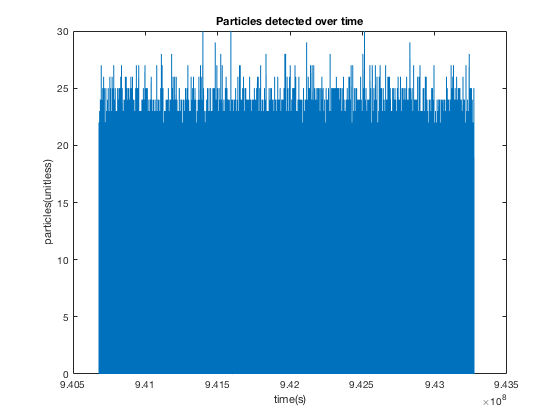

figure;
plot(timeData,partData);
xlabel('time(s)'), ylabel('particles(unitless)');
title('Particles detected over time');

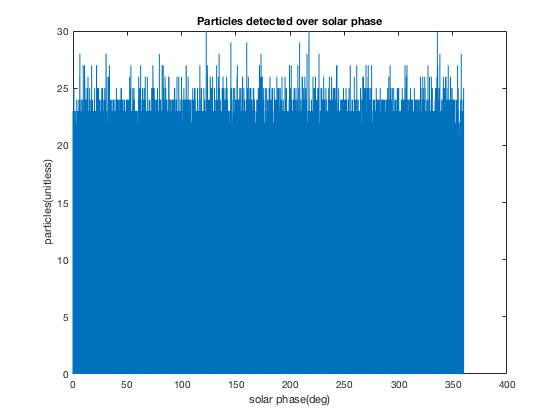

figure;
plot(sphaseData,partData);
xlabel('solar phase(deg)'), ylabel('particles(unitless)');
title('Particles detected over solar phase');

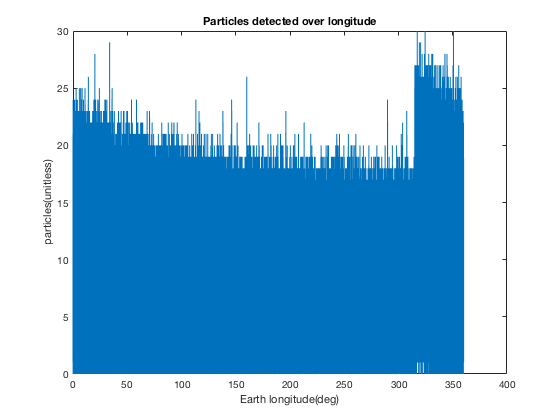

figure;
plot(longData,partData);
xlabel('Earth longitude(deg)'), ylabel('particles(unitless)');
title('Particles detected over longitude');

My predictions for the plots were correct for particles over time and solar phase, but there is an interesting (read:unexpected) pattern for particles over longitude. It seems to decrease in a 1/x -tail-like pattern (the tail of 1/x far away from zero), and then spikes up at around 310-315 degrees (estimate).

From these plots, it seems that there is some signal contamination happening with the data associated with the Earth longitude. It has a consistent effect described in the paragraph above, most notably the spike around 310 degrees that then slowly decreases. This also suggests that there is another small fall around 360 degrees, since the values for 360 and 0 are slightly off. The other two plots, however, do not provide enough information to tell if there is contamination happening.

I want to explore some possible changes of signal over time, so I will select several ranges of times at the beginning of the time data, at the middle, and at the end, and plot vs respective data for particle number. I will choose a range of ~3000 data points.

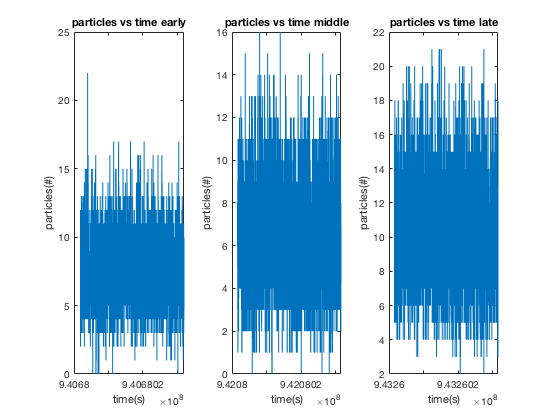

figure;
subplot(1,3,1);
plot(timeData(30:3030,1),partData(30:3030,1));
xlabel('time(s)'), ylabel('particles(#)');
title('particles vs time early');
subplot(1,3,2);
plot(timeData(14000000:14003000,1),partData(14000000:14003000,1));
xlabel('time(s)'), ylabel('particles(#)');
title('particles vs time middle');
subplot(1,3,3);
plot(timeData(25800000:25803000,1),partData(25800000:25803000,1));
xlabel('time(s)'), ylabel('particles(#)');
title('particles vs time late');

With simply looking at the data, it suggests that the average values have shifted quite a bit depending on the time range. Just to make sure that I am not happening to only encapsulate certain ranges of Earth's longitudes (as that was a factor seen from previous plots), I will try out a couple of other ranges nearby.

One of the things I've found (manually) is that 3000 data points is a change of 20 degrees exactly for the Earth's longitude data. The three ranges I've plotted happened to correspond to these data values.

Early:

longData(30)%lower bound

ans = 45.1933

longData(3030)%upper bound

ans = 65.1933

Middle:

longData(14000000)%lower bound

ans = 138.3267

longData(14003000)%upper bound

ans = 158.3267

Late:

longData(25800000)%lower bound

ans = 324.9933

longData(25803000)%upper bound

ans = 344.9933

I want to replot the above graphs with different ranges in the same ballpark of timezones to make sure that the data is not contaminated by the effects of longitude variation in signal. I will aim to place the data near the 45-65 degree range (longitude).

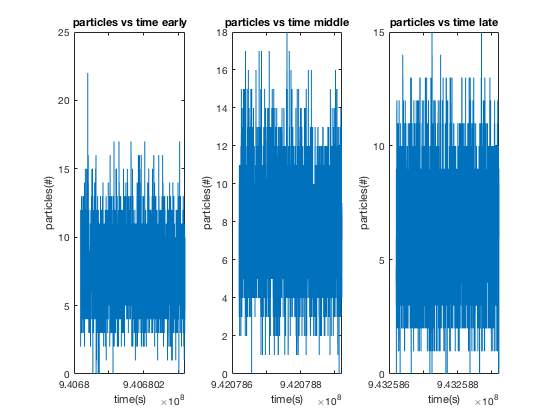

figure;
subplot(1,3,1);
plot(timeData(30:3030,1),partData(30:3030,1));
xlabel('time(s)'), ylabel('particles(#)');
title('particles vs time early');
subplot(1,3,2);
plot(timeData(13986050:13989050,1),partData(13986050:13989050,1));
xlabel('time(s)'), ylabel('particles(#)');
title('particles vs time middle');
subplot(1,3,3);
plot(timeData(25786050:25789050,1),partData(25786050:25789050,1));
xlabel('time(s)'), ylabel('particles(#)');
title('particles vs time late');

The data is in fact quite different. This shows that although the signal does change with time, the average value of the signal does not shift significantly (from manual observation of the graphs), but it does become significantly noisier. This suggests that our background should have some time-dependence to it.

I expect that there is some distribution of recordings over a fixed interval in time and longitude (or solar phase). Due to the changes in counts based on longitude and time, I expect that there will be different distributions if we change either of the intervals — changing longitude should change the mean value of the distribution, while changing time will have some effect that I'm not quite sure of yet (we saw data got noisier, but unsure how the distribution will change).

It seems that there are points of signal contamination, as there are some points that are outliers on all of our plots (high = signal). I plan to build a background distribution by plotting the number of counts for some range of time and longitude over each signal value seen in that range.

*2) Find and describe as accurately as you can how the background changes.*

I want to look at one period of values at some early time and see how the number of counts is distributed based on each value of signal. Since 20 degrees of longitude was 3000 points exactly, 1 period = 360 degrees = 3000 * 18 points.

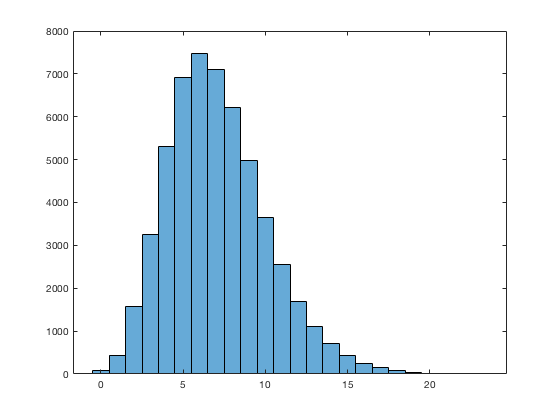

figure;
ePpart = partData(30:54030,1);
ePtime = timeData(30:54030,1);
histogram(ePpart);

This looks like a Poisson distribution. It is a bit hard to tell if there is signal contamination from this distribution, so I want to create another Poisson with a mean of 6 and a comparable number of data points to see any differences.

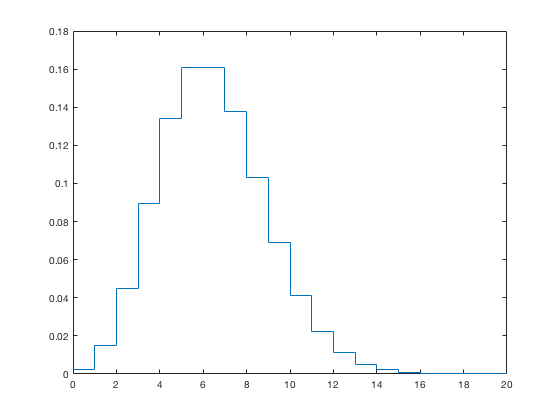

figure;
test = makedist('Poisson',"lambda",6);
x = 0:20;
testPDF = pdf(test,x);
stairs(x,testPDF);

This was a bit ambitious, it is very difficult to tell just from this plot if there is signal contamination.

I want to check histograms of different periods over time, and will use periods surrounding times used in last section (early, mid, and late). Early has already just been checked.

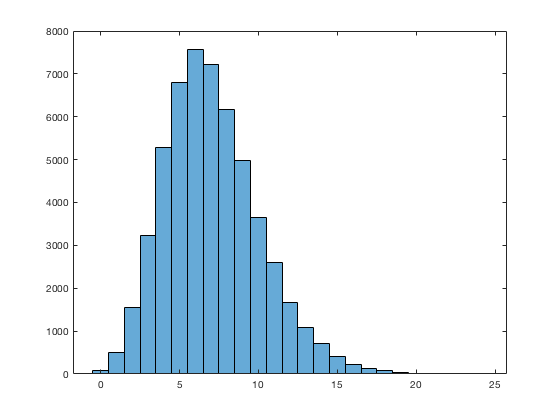

figure;
mPpart = partData(13986050:14040050,1);
mPtime = timeData(13986050:14040050,1);
histogram(mPpart);

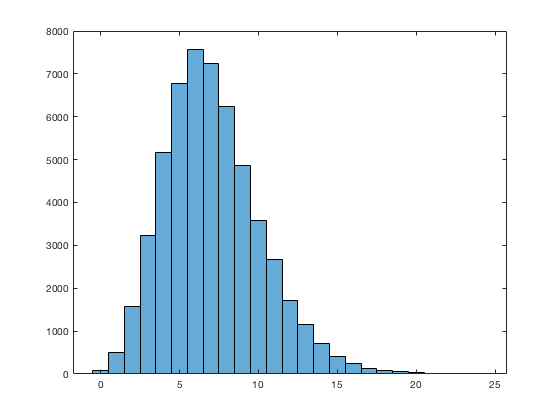

figure;
lPpart = partData(25786050:25840050,1);
lPtime = timeData(25786050:25840050,1);
histogram(lPpart);

All of the histograms, surprisingly, look about the same. These are at wildly different times, but over a whole longitude period. Even though the data above was quite noisy, the distributions seem to be about the same.

I think the "time"-variation of the background distribution is better thought of as variation over the period of measurement (the Earth's longitude). This is suggested by the lack of variation in background at different observations over whole periods in time, but consistent differences of signal over longitudinal angles. This is easier portrayed by the fact that different time measurements correspond to different points on the periodic behavior of signal over the longitude, so that dependence is what I want to investigate.

zeroDeg = find(floor(longData) == 0);
sixDeg = find(floor(longData) == 60);
ninDeg = find(floor(longData) == 90);
otDeg = find(floor(longData) == 120);
oeDeg = find(floor(longData) == 180);
tfDeg = find(floor(longData) == 240);
tnDeg = find(floor(longData) == 290);
ttDeg = find(floor(longData) == 310);
tf2Deg = find(floor(longData) == 340);

These degree boundaries were decided on by looking at the plot of signal vs longitude as one of the first three plots in part 1.

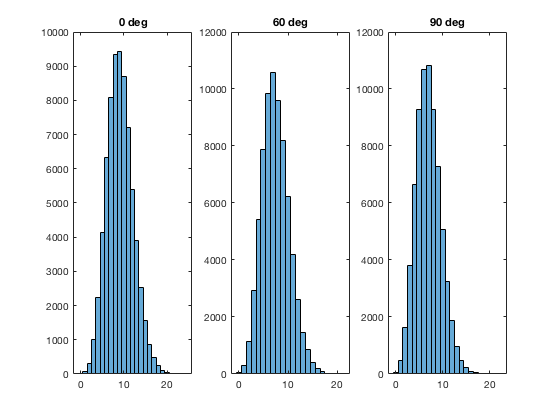

figure;
subplot(1,3,1);
histogram(partData(zeroDeg));
title('0 deg');
subplot(1,3,2);
histogram(partData(sixDeg));
title('60 deg');
subplot(1,3,3);
histogram(partData(ninDeg));
title('90 deg');

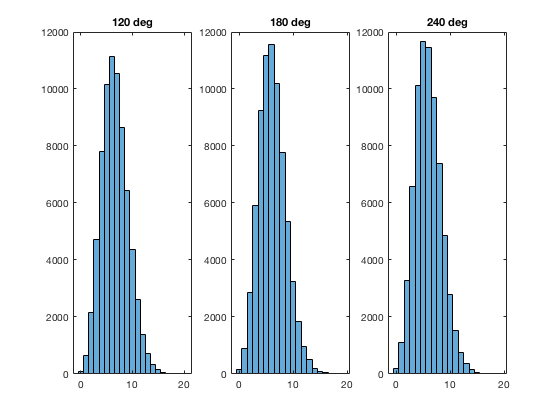

figure;
subplot(1,3,1);
histogram(partData(otDeg));
title('120 deg');
subplot(1,3,2);
histogram(partData(oeDeg));
title('180 deg');
subplot(1,3,3);
histogram(partData(tfDeg));
title('240 deg');

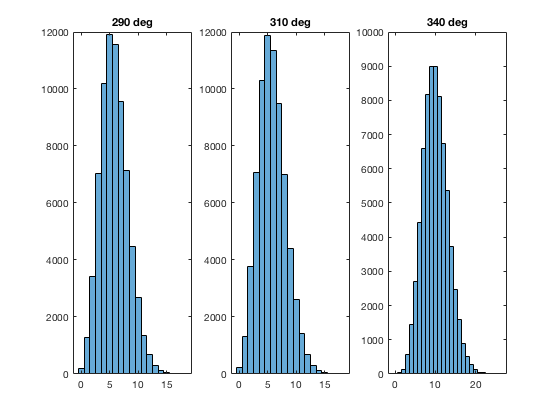

figure;
subplot(1,3,1);
histogram(partData(tnDeg));
title('290 deg');
subplot(1,3,2);
histogram(partData(ttDeg));
title('310 deg');
subplot(1,3,3);
histogram(partData(tf2Deg));
title('340 deg');

It is quite clear from these histograms that the background is longitude-dependent. The values of the mean shift drastically depending on the longitudinal degree (note especially change between 310 degree and 340 degree histograms). This means that the background model at different longitudinal angles should be different.

*3) Create a model for the background that includes time dependence, and explicitly compare your model to the data. How good is your model of the background?*

For each of the above-plotted histograms, I want to create a background Poisson distribution centered at the mean, and see how the histograms compare to my created background.

First, I want to find the mean of each histogram (and display it).

meanZero = floor(mean(partData(zeroDeg)))

meanZero = 9

meanSix = floor(mean(partData(sixDeg)))

meanSix = 7

meanNin = floor(mean(partData(ninDeg)))

meanNin = 6

meanOt = floor(mean(partData(otDeg)))

meanOt = 6

meanOe = floor(mean(partData(oeDeg)))

meanOe = 6

meanTf = floor(mean(partData(tfDeg)))

meanTf = 5

meanTn = floor(mean(partData(tnDeg)))

meanTn = 5

meanTt = floor(mean(partData(ttDeg)))

meanTt = 5

meanTf2 = floor(mean(partData(tf2Deg)))

meanTf2 = 9

Create Poisson distributions with the above mean values.

bgZ = makedist('Poisson',"lambda",meanZero);
bgS = makedist('Poisson',"lambda",meanSix);
bgNin = makedist('Poisson',"lambda",meanNin);
bgOt = makedist('Poisson',"lambda",meanOt);
bgOe = makedist('Poisson',"lambda",meanOe);
bgTf = makedist('Poisson',"lambda",meanTf);
bgTn = makedist('Poisson',"lambda",meanTn);
bgTt = makedist('Poisson',"lambda",meanTt);
bgTf2 = makedist('Poisson',"lambda",meanTf2);

Compare the histograms side by side. The backgrounds will not be scaled vertically.

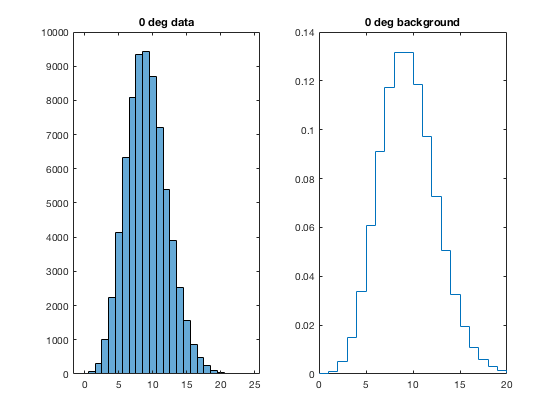

x = 0:20;
figure;
subplot(1,2,1);
histogram(partData(zeroDeg));
title('0 deg data');
subplot(1,2,2);
pdfZ = pdf(bgZ,x);
stairs(x,pdfZ);
title('0 deg background')

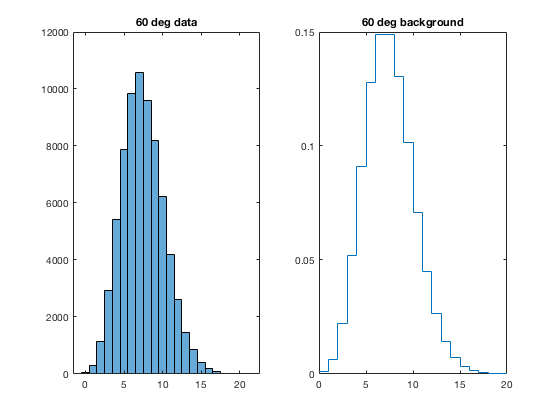

figure;
subplot(1,2,1);
histogram(partData(sixDeg));
title('60 deg data');
subplot(1,2,2);
pdfSix = pdf(bgS,x);
stairs(x,pdfSix);
title('60 deg background');

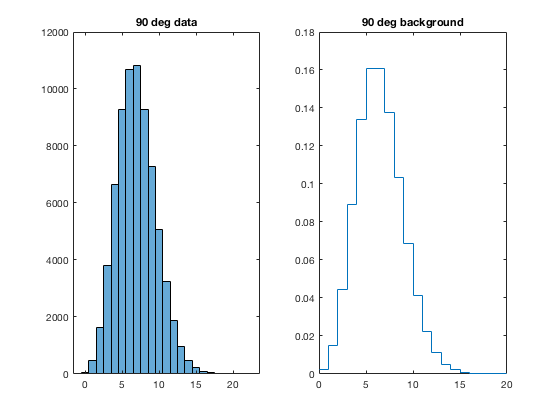

figure;
subplot(1,2,1);
histogram(partData(ninDeg));
title('90 deg data');
subplot(1,2,2);
pdfNin = pdf(bgNin,x);
stairs(x,pdfNin);
title('90 deg background');

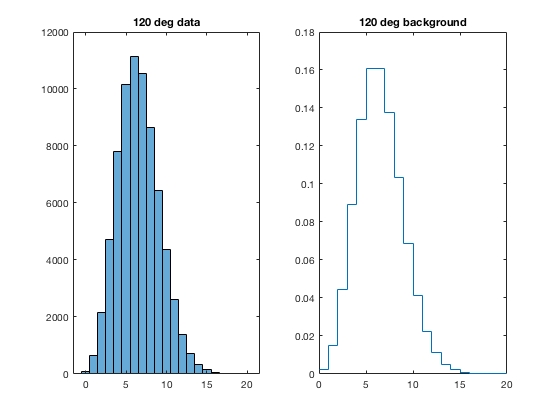

figure;
subplot(1,2,1);
histogram(partData(otDeg));
title('120 deg data');
subplot(1,2,2);
pdfOt = pdf(bgOt,x);
stairs(x,pdfOt);
title('120 deg background');

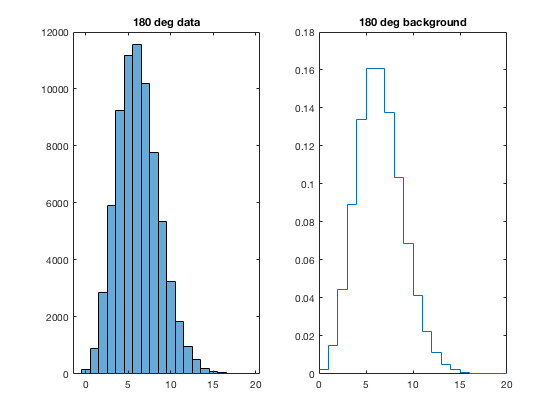

figure;
subplot(1,2,1);
histogram(partData(oeDeg));
title('180 deg data');
subplot(1,2,2);
pdfOe = pdf(bgOe,x);
stairs(x,pdfOe);
title('180 deg background');

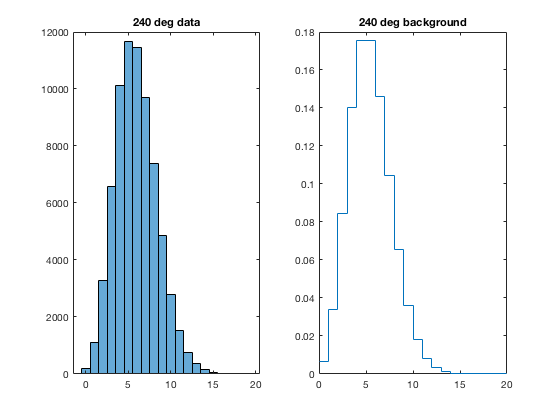

figure;
subplot(1,2,1);
histogram(partData(tfDeg));
title('240 deg data');
subplot(1,2,2);
pdfTf = pdf(bgTf,x);
stairs(x,pdfTf);
title('240 deg background');

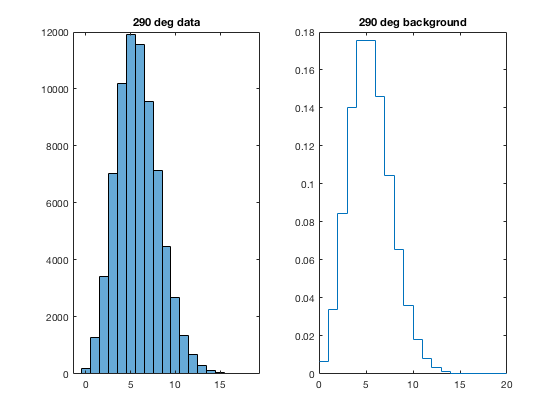

figure;
subplot(1,2,1);
histogram(partData(tnDeg));
title('290 deg data');
subplot(1,2,2);
pdfTn = pdf(bgTn,x);
stairs(x,pdfTn);
title('290 deg background');

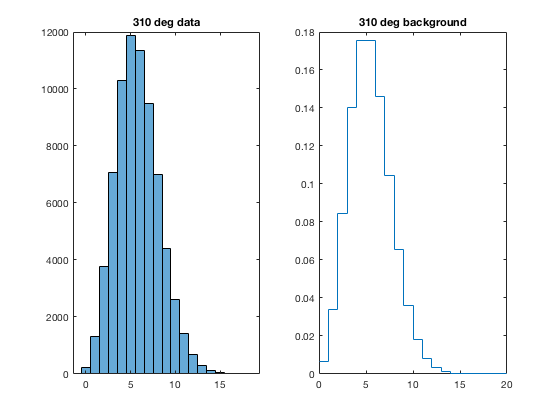

figure;
subplot(1,2,1);
histogram(partData(ttDeg));
title('310 deg data');
subplot(1,2,2);
pdfTt = pdf(bgTt,x);
stairs(x,pdfTt);
title('310 deg background')

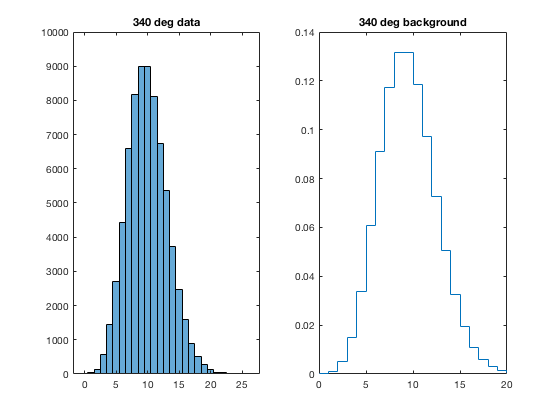

figure;
subplot(1,2,1);
histogram(partData(tf2Deg));
title('340 deg data');
subplot(1,2,2);
pdfTf2 = pdf(bgTf2,x);
stairs(x,pdfTf2);
title('340 deg background');

The backgrounds seem to fit pretty well! Of course, there is a caveat, that in creating these backgrounds I assumed no signal contamination, which there should be. Nonetheless, the background fitting seems successful.

*4) Because the background varies, your discovery sensitivity threshold (how many particles you would need to see) also varies. What is the '5-sigma' threshold for a 100 millisecond GRB at different times?*

100ms is precisely one interval of our observation, so it would be one data point (instead of multiple data points stretched over some time interval).

We can calculate 5 sigma events for each of the above-created Poisson backgrounds.

thZ = 1 - cdf(bgZ,)

**Problem 2**

*2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf().*

I am pursuing transient data.

Import all of the data and split into individual images.

h5disp('lab4images.h5')

HDF5 lab4images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata2 = h5read("lab4images.h5",'/imagestack');
image1 = squeeze(mydata2(1,:,:));
image2 = squeeze(mydata2(2,:,:));
image3 = squeeze(mydata2(3,:,:));
image4 = squeeze(mydata2(4,:,:));
image5 = squeeze(mydata2(5,:,:));
image6 = squeeze(mydata2(6,:,:));
image7 = squeeze(mydata2(7,:,:));
image8 = squeeze(mydata2(8,:,:));
image9 = squeeze(mydata2(9,:,:));
image10 = squeeze(mydata2(10,:,:));

Look at all of the images.

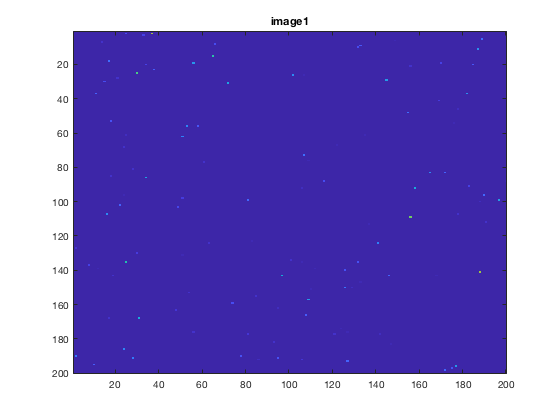

figure;
image(image1);
title('image1');

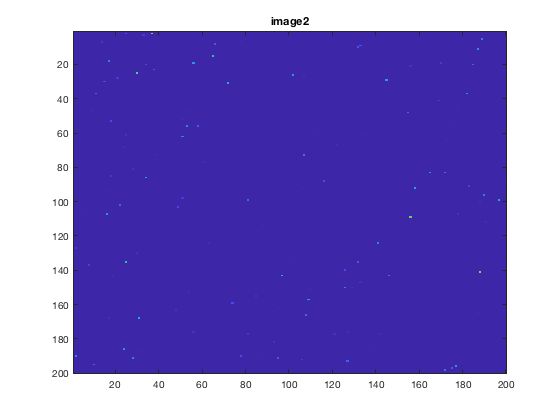

figure;
image(image2);
title('image2');

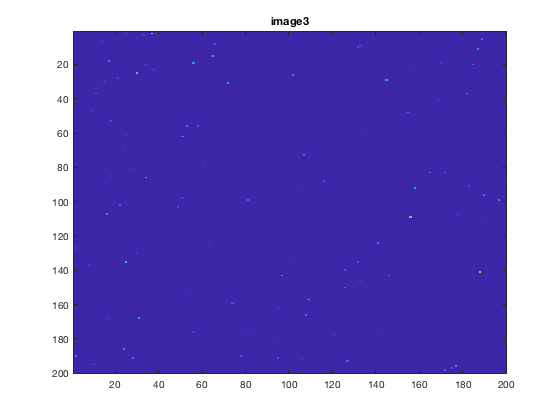

figure;
image(image3);
title('image3');

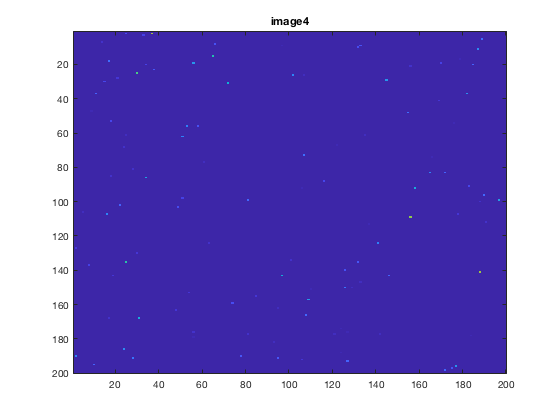

figure;
image(image4);
title('image4');

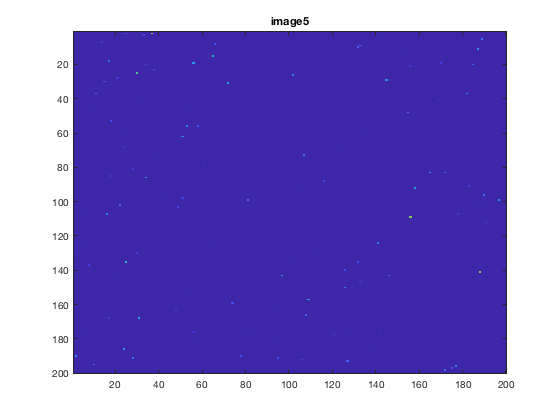

figure;
image(image5);
title('image5');

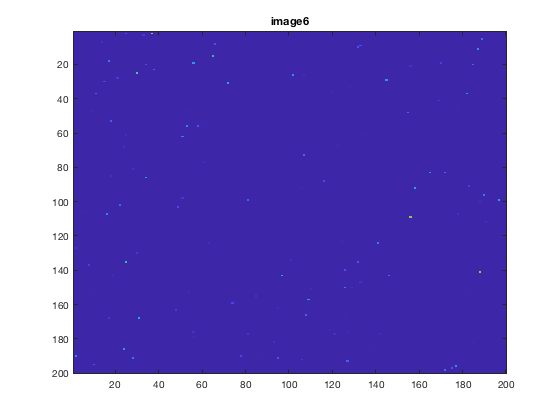

figure;
image(image6);
title('image6');

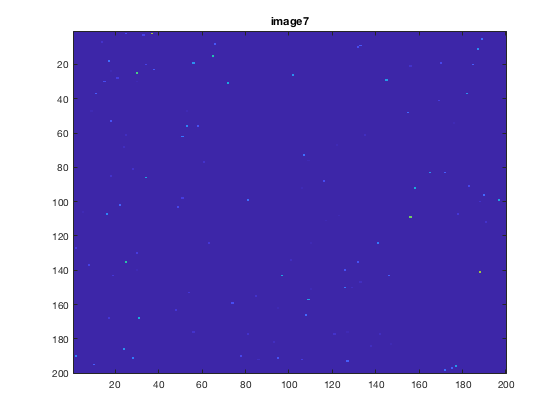

figure;
image(image7);
title('image7');

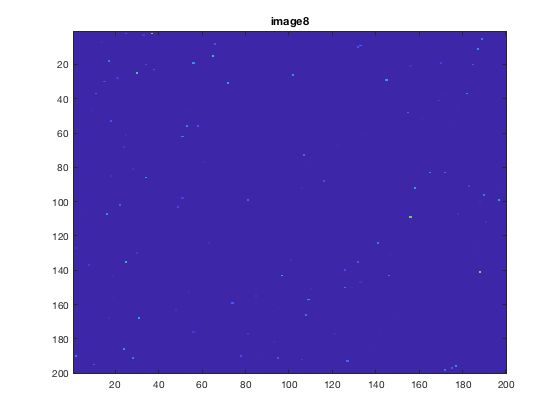

figure;
image(image8);
title('image8');

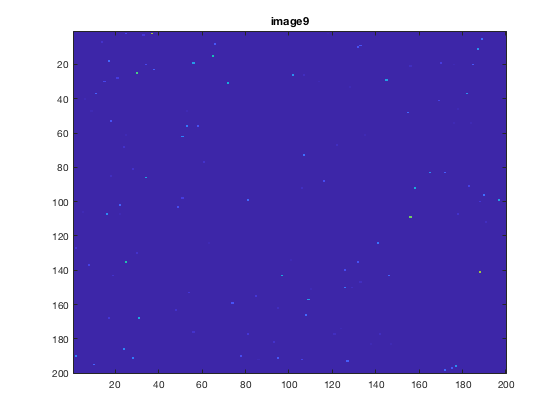

figure;
image(image9);
title('image9');

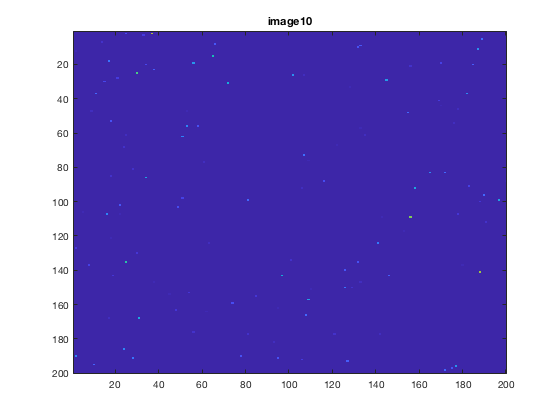

figure;
image(image10);
title('image10');

It looks like the images contain a blue background with faint dots corresponding to some sort of signal.

*3) Using your background distribution, hunt for your signal. Describe what you found.*

*4) You and your lab partner had diffeernt pdf(), but were using the same data. Explore why this is.*